# Testing april tag localization

initialize ros

init_ROS();

Shutting down global node /matlab_global_node_08530 with NodeURI http://192.168.16.71:37629/ and MasterURI http://192.168.16.71:11311/.
Initializing global node /matlab_global_node_57641 with NodeURI http://192.168.16.71:45713/ and MasterURI http://192.168.16.71:11311/.
ROS initialization complete! :-)


## Create cam object

calib_params = load("camera_calibration/calib_1024x768/cameraParams.mat");
cam_intrinsics = calib_params.cameraParams.Intrinsics;
cam = Camera_ROS(cam_intrinsics);
%cam.config_resolution('1024x768');
pause(1);

## get image from camera and display tag detection

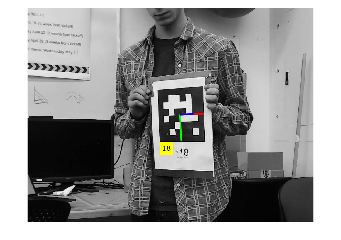

img = rgb2gray(cam.get_image_raw());
[img_undistort, new_center] = cam.undistort_image(img);

img = rgb2gray(cam.get_image_raw());
% display april tag detection
try
    [num_tags, tag_ids, tag_img_corners, tag_poses] = AprilTags.detect_tags_in_image(img_undistort, cam_intrinsics);
    tag_area = polyarea(tag_img_corners(:,1), tag_img_corners(:,2));
    [img_undistort, new_center] = cam.undistort_image(img);
    img_tags_draw = AprilTags.draw_tags_on_image(img_undistort, cam_intrinsics, num_tags, tag_ids, tag_img_corners, tag_poses);
    figure
    imshow(img_tags_draw);
catch
    figure
    imshow(img_undistort);
end

tag_poses.Rotation

ans =     0.8613    0.0014   -0.5080
    0.0395    0.9968    0.0697
    0.5065   -0.0801    0.8585


## plotting

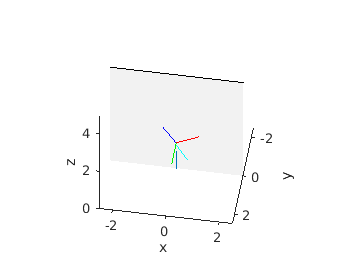

figure; hold on
% plot styling
axis equal
xlim([-2.5 2.5]); ylim([-2.5 2.5]); zlim([0 5])
xlabel("x"); ylabel("y"); zlabel("z")
view([0 0.01])

% plot patch for x-z plane
s = 5;
patch([s -s -s s], [0 0 0 0], [s s -s -s], [s s -s -s], "FaceColor", "k", "FaceAlpha", 0.05)

% plot camera heading vector at [0,0,0]
quiver3(0, 0, 0, 0, 0, 1)

% plot apriltag axes in space
tag_quat = rotm2quat(tag_poses.Rotation);
plotTransforms(tag_poses.Translation, tag_quat)

% plot projected april tag normal vector
tag_x = tag_poses.Translation(1);
tag_y = -tag_poses.Translation(2); % not sure why it's negative
tag_z = tag_poses.Translation(3);  % depth
tag_rot_x = tag_poses.Rotation(:, 1);
tag_rot_z = tag_poses.Rotation(:, 3);
% quiver3(tag_x, tag_y,tag_z, -tag_poses.Rotation(1,3), -tag_poses.Rotation(2,3), -tag_poses.Rotation(3,3), Color="k")
quiver3(tag_x, 0,tag_z, -tag_poses.Rotation(1,3), 0, -tag_poses.Rotation(3,3), Color="c")

## localize from april tag

here's where it gets somewhat confusing...

the apriltag detection gives the displacement of the tag from the camera's frame of reference in a vector of `[x y z]`. The `x` axis is defined in the camera's frame as rightward positive, the `y` axis is upward positive, the `z` axis is forward positive. We need to project the april tag's normal vector into the `xz` plane, then redefine it as existing in an `xy` plane, where x is rightward positive and `y` is forward positive. This fits with the 2D `xy` localization the robot is working with.

% plot setup
% figure;
% subplot(1, 2, 1)
% hold on; axis equal; grid on; xlabel("x"); ylabel("y")
% s = 3; xlim([-s s]); ylim([0 2*s])

tag_pose_cam_frame = Pose2d.from_xyrot(tag_x, tag_z, Rotation2d(tag_rot_z(1), -tag_rot_z(3)));
tag_pose_cam_frame.translation

ans =   Translation2d with properties:

    val_x: -0.0272
    val_y: 1.2588


tag_pose_cam_frame.rotation

ans =   Rotation2d with properties:

    value_radians: -2.1051
          vec_cos: -0.5093
          vec_sin: -0.8606


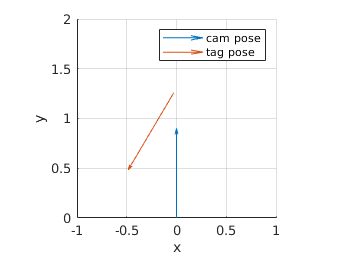


cam_pose_cam_frame = Pose2d.from_xydeg(0, 0, 90);

figure; hold on; axis equal; grid on; xlabel("x"); ylabel("y")
xlim([-1, 1]); ylim([0, 2])
quiver_pose(cam_pose_cam_frame)
quiver_pose(tag_pose_cam_frame)
legend("cam pose", "tag pose")

% transform to get from tag frame to cam frame
cam_to_tag_trans = Transform2d(tag_pose_cam_frame.translation.unary_minus, tag_pose_cam_frame.rotation.minus)

Unrecognized method, property, or field 'rotateBy' for class 'Rotation2d'.

Error in  -  (line 51)
            r2d_minus = obj.rotateBy(other.unary_minus());

% cam_pose_tag_frame = cam_pose_cam_frame.relative_to(tag_pose_cam_frame);
cam_pose_tag_frame = cam_pose_cam_frame.transform_by(cam_to_tag_trans)

cam_pose_tag_frame.translation

function quiver_pose(pose)
    quiver(pose.translation.val_x, pose.translation.val_y,...
       pose.rotation.vec_cos, pose.rotation.vec_sin);
end